Data Science (Prof. Neff)                    Abgabedatum 17.11.2020

Durchführung einer MSA nach Verfahren 1 und 2

Gruppe 6:    Benjamin Hamm (2060696), Jan Klotter (2060690),

                    Anna Kuhn (2051063), Michael Schulze (2061282)

# MSA Verfahren 1

%Messwerte des Verfahren 1
data_jan = readtable("MSA_Verfahren1_200ml_Jan.csv")

data_jan = 25×1 table
    Gewicht_in_g
    ____________

        199     
        213     
        185     
        198     
        205     
        191     
        184     
        193     
        199     
        206     
        207     
        210     
        213     
        197     
        205     
        203     


data_benni = readtable("MSA_Verfahren1_200ml_Benjamin.csv")

data_benni = 25×1 table
    Gewicht_in_g
    ____________

        195     
        199     
        201     
        209     
        192     
        193     
        199     
        192     
        201     
        202     
        205     
        210     
        196     
        197     
        195     
        192     


data_anna = readtable("MSA_Verfahren1_200ml_Anna.csv")

data_anna = 25×1 table
    Gewicht_in_g
    ____________

        201     
        194     
        192     
        195     
        195     
        204     
        201     
        202     
        195     
        201     
        203     
        201     
        198     
        202     
        200     
        204     


data_michael = readtable("MSA_Verfahren1_200ml_Michael.csv")

data_michael = 25×1 table
    Gewicht_in_g
    ____________

        205     
        209     
        210     
        204     
        208     
        209     
        208     
        206     
        208     
        205     
        202     
        209     
        204     
        207     
        208     
        204     



%Statistische Kenngrößen
Mean_Jan = mean(data_jan.Gewicht_in_g)

Mean_Jan = 200.0400

Std_Jan = std(data_jan.Gewicht_in_g)

Std_Jan = 7.8818

Mean_Benni = mean(data_benni.Gewicht_in_g)

Mean_Benni = 198.7200

Std_Benni = std(data_benni.Gewicht_in_g)

Std_Benni = 5.0705

Mean_Anna = mean(data_anna.Gewicht_in_g)

Mean_Anna = 199.7600

Std_Anna = std(data_anna.Gewicht_in_g)

Std_Anna = 3.6774

Mean_Michael = mean(data_michael.Gewicht_in_g)

Mean_Michael = 206.8800

Std_Michael = std(data_michael.Gewicht_in_g)

Std_Michael = 2.2045

## Messmittel der verschiedenen Kandidaten

% Fähigkeitskennzahl (Messmittelfähigkeit) cg 
% cg = (a * Tb) / (6 * Std_g)
% a - Faktor, typisch 0.2
% Tb - Toleranzbreite (Messbereich, z.B. 500 ml)
% Std_g - Standardabweichung des Messmittels

% kritische Fähigkeitskennzahl (kritische Messmittelfähigkeit) cgk
% cgk = (a/2 * Tb - abs(mean - Refwert) / (3 * Std_g)
% a - Faktor, typisch 0.2
% Tb - Toleranzbreite (Messbereich, z. B. 500 ml)
% mean - Mittelwert der Messwerte, z. B. aus 25 mal 200 ml messen
% Std_g - Standardabweichung des Messmittels

cg_Jan = 0.2 * 500 / (6*Std_Jan)

cg_Jan = 2.1146

cg_k_Jan = ((0.2/2)*500-abs(Mean_Jan-200))/(3*Std_Jan)

cg_k_Jan = 2.1129

cg_Benni = 0.2 * 500 / (6*Std_Benni)

cg_Benni = 3.2870

cg_k_Benni = ((0.2/2)*500-abs(Mean_Benni-200))/(3*Std_Benni)

cg_k_Benni = 3.2028

cg_Anna = 0.2 * 500 / (6*Std_Anna)

cg_Anna = 4.5322

%cg_anna_matlab = capability(data_anna.Gewicht_in_g,[0,200])
cg_k_Anna = ((0.2/2)*500-abs(Mean_Anna-200))/(3*Std_Anna)

cg_k_Anna = 4.5104

cg_Michael = 0.2 * 500 / (6*Std_Michael)

cg_Michael = 7.5602

cg_k_Michael = ((0.2/2)*500-abs(Mean_Michael-200))/(3*Std_Michael)

cg_k_Michael = 6.5199


% Beurteilung Messgerätefähigkeit
cg_min = 1.0;
cgk_min = 1.33;

text = sprintf("cg_Jan: %0.4f %s %0.4f und cg_k_Jan: %0.4f %s %0.4f, ..." + ...
    "somit Messgerät fähig",cg_Jan, char(8805), cg_min, cg_k_Jan, ...
    char(8805), cgk_min);
disp(text)

cg_Jan: 2.1146 ≥ 1.0000 und cg_k_Jan: 2.1129 ≥ 1.3300, ...somit Messgerät fähig


text = sprintf("cg_Benni: %0.4f %s %0.4f und cg_k_Benni: %0.4f %s %0.4f, ..." + ...
    "somit Messgerät fähig",cg_Benni, char(8805), cg_min, cg_k_Benni, ...
    char(8805), cgk_min);
disp(text)

cg_Benni: 3.2870 ≥ 1.0000 und cg_k_Benni: 3.2028 ≥ 1.3300, ...somit Messgerät fähig


text = sprintf("cg_Anna: %0.4f %s %0.4f und cg_k_Anna: %0.4f %s %0.4f, somit ..." + ...
    "Messgerät fähig",cg_Anna, char(8805), cg_min, cg_k_Anna, ...
    char(8805), cgk_min);
disp(text)

cg_Anna: 4.5322 ≥ 1.0000 und cg_k_Anna: 4.5104 ≥ 1.3300, somit ...Messgerät fähig


text = sprintf("cg_Michael: %0.4f %s %0.4f und cg_k_Michael: %0.4f %s %0.4f, ..." + ...
    "somit Messgerät fähig",cg_Michael, char(8805), cg_min, cg_k_Michael, ...
    char(8805), cgk_min);
disp(text)

cg_Michael: 7.5602 ≥ 1.0000 und cg_k_Michael: 6.5199 ≥ 1.3300, ...somit Messgerät fähig


## Lineare Anpassung

%Prüfung auf auf Wiederholpräzision
x = (1:1:25);

linreg_jan = fitlm(x,data_jan.Gewicht_in_g,"linear")

linreg_jan = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate      SE        tStat       pValue  
                   ________    _______    _______    __________

    (Intercept)      199.36     3.3157     60.126    8.4599e-27
    x1             0.052308    0.22304    0.23452       0.81665


Number of observations: 25, Error degrees of freedom: 23
Root Mean Squared Error: 8.04
R-squared: 0.00239,  Adjusted R-Squared: -0.041
F-statistic vs. constant model: 0.055, p-value = 0.817

linreg_benni = fitlm(x,data_benni.Gewicht_in_g,"linear")

linreg_benni = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate       SE        tStat        pValue  
                   _________    _______    ________    __________

    (Intercept)       199.38     2.1298      93.615    3.3318e-31
    x1             -0.050769    0.14326    -0.35437       0.72629


Number of observations: 25, Error degrees of freedom: 23
Root Mean Squared Error: 5.17
R-squared: 0.00543,  Adjusted R-Squared: -0.0378
F-statistic vs. constant model: 0.126, p-value = 0.726

linreg_anna = fitlm(x,data_anna.Gewicht_in_g,"linear")

linreg_anna = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate       SE       tStat       pValue  
                   ________    ________    ______    __________

    (Intercept)     197.49       1.4512    136.09    6.1999e-35
    x1             0.17462     0.097617    1.7888      0.086832


Number of observations: 25, Error degrees of freedom: 23
Root Mean Squared Error: 3.52
R-squared: 0.122,  Adjusted R-Squared: 0.084
F-statistic vs. constant model: 3.2, p-value = 0.0868

linreg_michael = fitlm(x,data_michael.Gewicht_in_g,"linear")

linreg_michael = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                    Estimate        SE         tStat        pValue  
                   __________    ________    _________    __________

    (Intercept)         206.9     0.92849       222.83    7.4203e-40
    x1             -0.0015385    0.062457    -0.024632       0.98056


Number of observations: 25, Error degrees of freedom: 23
Root Mean Squared Error: 2.25
R-squared: 2.64e-05,  Adjusted R-Squared: -0.0435
F-statistic vs. constant model: 0.000607, p-value = 0.981



slope_jan = linreg_jan.Coefficients.Estimate(2);
intercept_jan = linreg_jan.Coefficients.Estimate(1);
y_jan = slope_jan * x + intercept_jan;

slope_benni = linreg_benni.Coefficients.Estimate(2);
intercept_benni = linreg_benni.Coefficients.Estimate(1);
y_benni = slope_benni * x + intercept_benni;

slope_anna = linreg_anna.Coefficients.Estimate(2);
intercept_anna = linreg_anna.Coefficients.Estimate(1);
y_anna = slope_anna * x + intercept_anna;

slope_michael = linreg_michael.Coefficients.Estimate(2);
intercept_michael = linreg_michael.Coefficients.Estimate(1);
y_michael = slope_michael * x + intercept_michael;


## Plot aller Messwerte und der Ausgleichsgerade

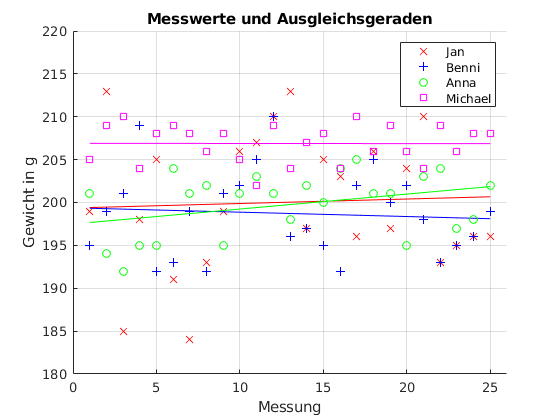

figure
hold on
ms1_jan = plot(x,data_jan.Gewicht_in_g,"rx");
plt_linreg_jan = plot(x, y_jan,"r");

ms1_benni = plot(x, data_benni.Gewicht_in_g, "b+");
plt_linreg_benni = plot(x, y_benni, "b");

ms1_anna = plot(x,data_anna.Gewicht_in_g, "go");
plt_linreg_anna = plot(x, y_anna, "g");

ms1_michael = plot(x, data_michael.Gewicht_in_g, "ms");
plt_linreg_michael = plot(x, y_michael, "m");

hold off
title("Messwerte und Ausgleichsgeraden");
xlabel("Messung");
ylabel("Gewicht in g");
legend([ms1_jan ms1_benni ms1_anna ms1_michael], ...
    ["Jan","Benni", "Anna","Michael"]);
xlim([0.0000 26]);
ylim([180 220]);
grid on

#  MSA Verfahren 2

%Messwerte Verfahren 2
data_ms2_jan = readtable('Messwerte_MSA2_Jan.xlsx')

data_ms2_jan = 30×4 table
    Operator    Part    Repetition    Measurement
    ________    ____    __________    ___________

    {'Jan'}      1          1             102    
    {'Jan'}      2          1             200    
    {'Jan'}      3          1             301    
    {'Jan'}      4          1             399    
    {'Jan'}      5          1             502    
    {'Jan'}      1          2              98    
    {'Jan'}      2          2             200    
    {'Jan'}      3          2             299    
    {'Jan'}      4          2             400    
    {'Jan'}      5          2             501    
    {'Jan'}      1          3             NaN    
    {'Jan'}      2          3             NaN    
    {'Jan'}      3          3             NaN    
    {'Jan'}      4          3             NaN    
    {'Jan'}      5          3        

data_ms2_benni = readtable('Messwerte_MSA2_Benjamin.xlsx')

data_ms2_benni = 30×4 table
      Operator      Part    Repetition    Measurement
    ____________    ____    __________    ___________

    {'Benjamin'}     1          1             101    
    {'Benjamin'}     2          1             198    
    {'Benjamin'}     3          1             299    
    {'Benjamin'}     4          1             402    
    {'Benjamin'}     5          1             500    
    {'Benjamin'}     1          2              99    
    {'Benjamin'}     2          2             202    
    {'Benjamin'}     3          2             298    
    {'Benjamin'}     4          2             397    
    {'Benjamin'}     5          2             503    
    {'Benjamin'}     1          3             NaN    
    {'Benjamin'}     2          3             NaN    
    {'Benjamin'}     3          3             NaN    
    {'Benjamin'}     4   

data_ms2_anna = readtable('Messwerte_MSA2_Anna.xlsx')

data_ms2_anna = 30×4 table
    Operator    Part    Repetition    Measurement
    ________    ____    __________    ___________

    {'Anna'}     1          1             100    
    {'Anna'}     2          1             204    
    {'Anna'}     3          1             303    
    {'Anna'}     4          1             409    
    {'Anna'}     5          1             506    
    {'Anna'}     1          2              99    
    {'Anna'}     2          2             201    
    {'Anna'}     3          2             300    
    {'Anna'}     4          2             406    
    {'Anna'}     5          2             503    
    {'Anna'}     1          3             NaN    
    {'Anna'}     2          3             NaN    
    {'Anna'}     3          3             NaN    
    {'Anna'}     4          3             NaN    
    {'Anna'}     5          3       

data_ms2_michael = readtable('Messwerte_MSA2_Micha.xlsx')

data_ms2_michael = 30×4 table
     Operator      Part    Repetition    Measurement
    ___________    ____    __________    ___________

    {'Michael'}     1          1             106    
    {'Michael'}     2          1             205    
    {'Michael'}     3          1             302    
    {'Michael'}     4          1             407    
    {'Michael'}     5          1             507    
    {'Michael'}     1          2             105    
    {'Michael'}     2          2             205    
    {'Michael'}     3          2             303    
    {'Michael'}     4          2             407    
    {'Michael'}     5          2             507    
    {'Michael'}     1          3             105    
    {'Michael'}     2          3             205    
    {'Michael'}     3          3             302    
    {'Michael'}     4          3      

## Streudiagramme

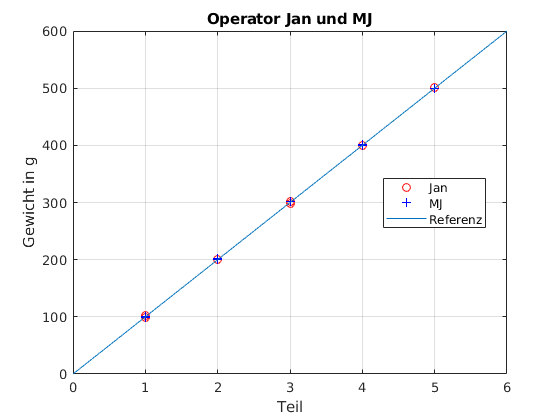


%gruppiertes Streudiagramm Jan
figure
gscatter(data_ms2_jan.Part,data_ms2_jan.Measurement,...
    data_ms2_jan.Operator,"rbg","o+x")
xlabel("Teil")
ylabel("Gewicht in g")
title("Operator Jan und MJ")
set(gca,'xtick',0:10)
ylim([0 600])
xlim([0 6])
refline(100,0)
legend({'Jan','MJ','Referenz'})
grid on

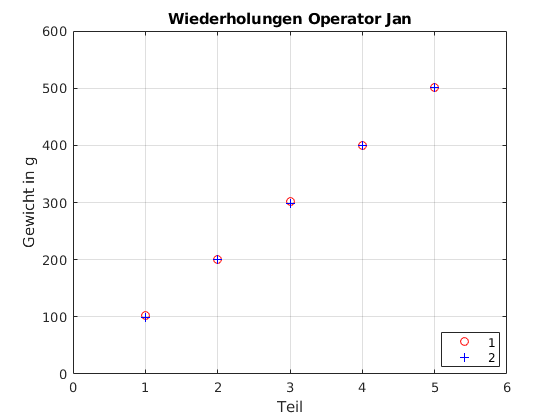

%nur Operator Jan
figure
gscatter(data_ms2_jan.Part(1:10),data_ms2_jan.Measurement(1:10),...
    data_ms2_jan.Repetition(1:10),"rbg","o+x")
title("Wiederholungen Operator Jan")
xlabel("Teil")
ylabel("Gewicht in g")
set(gca,'xtick',0:10)
ylim([0 600])
xlim([0 6])
grid on

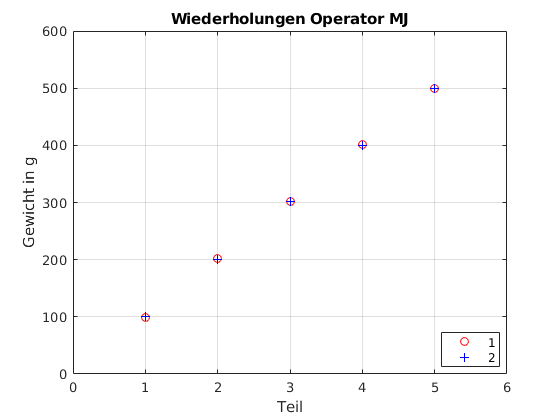

%nur Operator MJ
figure
gscatter(data_ms2_jan.Part(16:25),data_ms2_jan.Measurement(16:25),...
    data_ms2_jan.Repetition(16:25),"rbg","o+x")
title("Wiederholungen Operator MJ")
xlabel("Teil")
ylabel("Gewicht in g")
set(gca,'xtick',0:10)
ylim([0 600])
xlim([0 6])
grid on

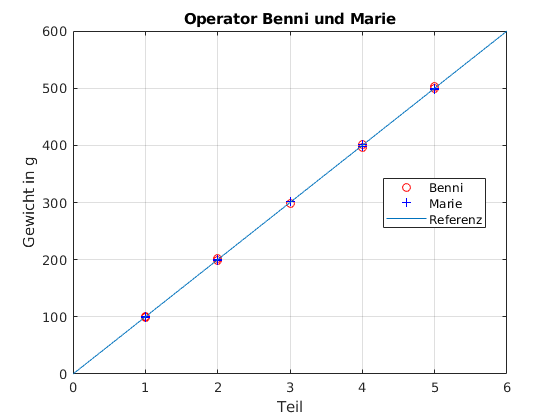

%gruppiertes Streudiagramm Benni
figure
gscatter(data_ms2_benni.Part,data_ms2_benni.Measurement,...
    data_ms2_benni.Operator,"rbg","o+x")
xlabel("Teil")
ylabel("Gewicht in g")
title("Operator Benni und Marie")
set(gca,'xtick',0:10)
ylim([0 600])
xlim([0 6])
refline(100,0)
legend({'Benni','Marie','Referenz'})
grid on

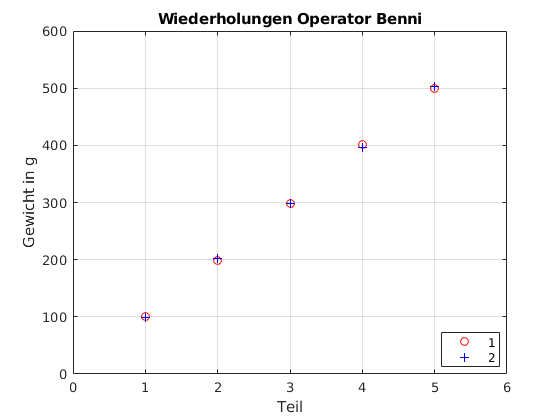

%nur Operator Benni
figure
gscatter(data_ms2_benni.Part(1:10),data_ms2_benni.Measurement(1:10),...
    data_ms2_benni.Repetition(1:10),"rbg","o+x")
title("Wiederholungen Operator Benni")
xlabel("Teil")
ylabel("Gewicht in g")
set(gca,'xtick',0:10)
ylim([0 600])
xlim([0 6])
grid on

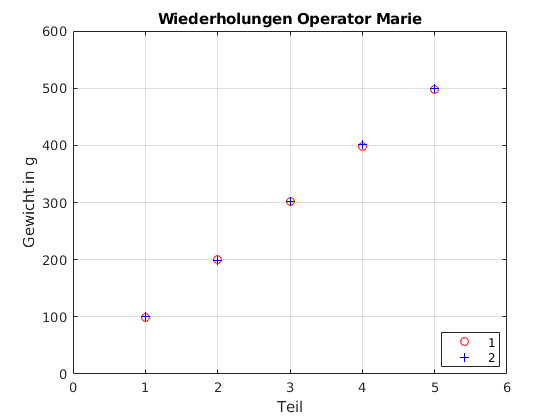

%nur Operator Marie
figure
gscatter(data_ms2_benni.Part(16:25),data_ms2_benni.Measurement(16:25),...
    data_ms2_benni.Repetition(16:25),"rbg","o+x")
title("Wiederholungen Operator Marie")
xlabel("Teil")
ylabel("Gewicht in g")
set(gca,'xtick',0:10)
ylim([0 600])
xlim([0 6])
grid on

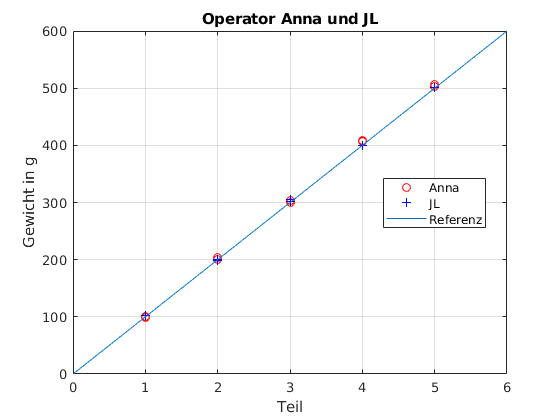

%gruppiertes Streudiagramm Anna
figure
gscatter(data_ms2_anna.Part,data_ms2_anna.Measurement,...
    data_ms2_anna.Operator,"rbg","o+x")
xlabel("Teil")
ylabel("Gewicht in g")
title("Operator Anna und JL")
set(gca,'xtick',0:10)
ylim([0 600])
xlim([0 6])
refline(100,0)
legend({'Anna','JL','Referenz'})
grid on

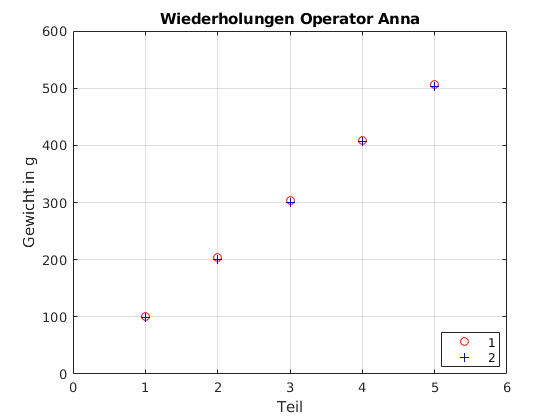

%nur Operator Anna
figure
gscatter(data_ms2_anna.Part(1:10),data_ms2_anna.Measurement(1:10),...
    data_ms2_anna.Repetition(1:10),"rbg","o+x")
title("Wiederholungen Operator Anna")
xlabel("Teil")
ylabel("Gewicht in g")
set(gca,'xtick',0:10)
ylim([0 600])
xlim([0 6])
grid on

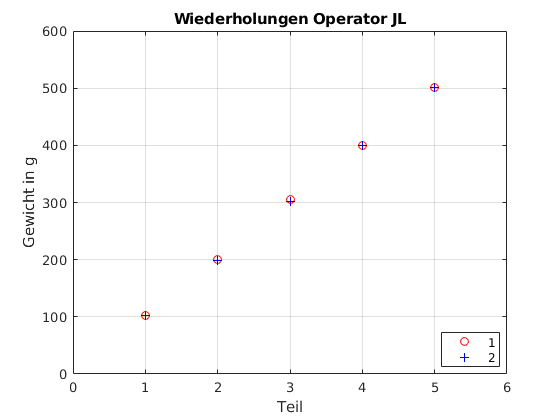

%nur Operator JL
figure
gscatter(data_ms2_anna.Part(16:25),data_ms2_anna.Measurement(16:25),...
    data_ms2_anna.Repetition(16:25),"rbg","o+x")
title("Wiederholungen Operator JL")
xlabel("Teil")
ylabel("Gewicht in g")
set(gca,'xtick',0:10)
ylim([0 600])
xlim([0 6])
grid on

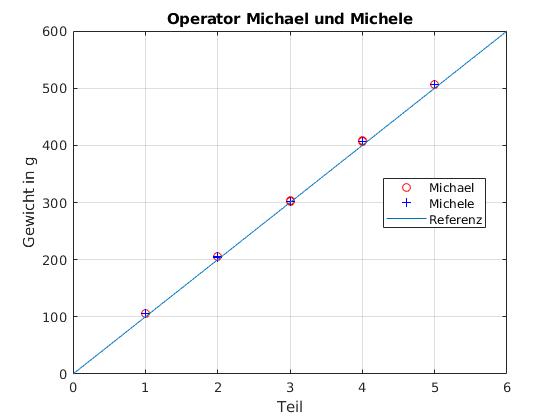

%gruppiertes Streudiagramm Michael
figure
gscatter(data_ms2_michael.Part,data_ms2_michael.Measurement,...
    data_ms2_michael.Operator,"rbg","o+x")
xlabel("Teil")
ylabel("Gewicht in g")
title("Operator Michael und Michele")
set(gca,'xtick',0:10)
ylim([0 600])
xlim([0 6])
refline(100,0)
legend({'Michael','Michele','Referenz'})
grid on

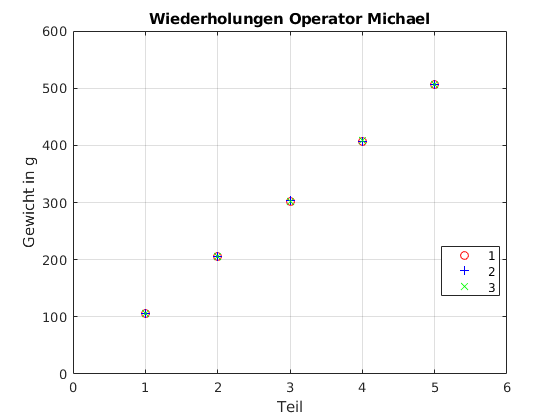

%nur Operator Michael
figure
gscatter(data_ms2_michael.Part(1:15),data_ms2_michael.Measurement(1:15),...
    data_ms2_michael.Repetition(1:15),"rbg","o+x")
title("Wiederholungen Operator Michael")
xlabel("Teil")
ylabel("Gewicht in g")
set(gca,'xtick',0:10)
ylim([0 600])
xlim([0 6])
grid on

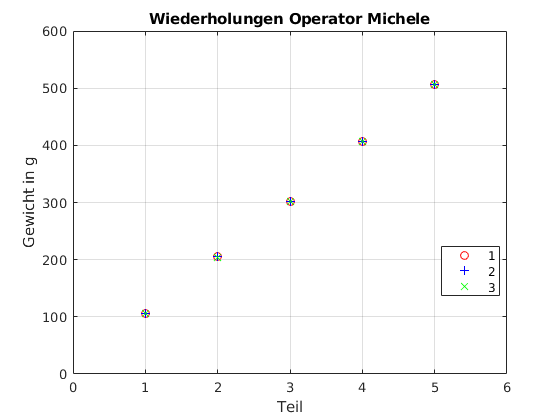

%nur Operator Michele
figure
gscatter(data_ms2_michael.Part(16:30),data_ms2_michael.Measurement(16:30),...
    data_ms2_michael.Repetition(16:30),"rbg","o+x")
title("Wiederholungen Operator Michele")
xlabel("Teil")
ylabel("Gewicht in g")
set(gca,'xtick',0:10)
ylim([0 600])
xlim([0 6])
grid on

## Boxplots

%Boxplot Jan
figure
boxplot(data_ms2_jan.Measurement,{data_ms2_jan.Part,...
    data_ms2_jan.Operator},"Colors","rg")
legend(findobj(gca,'Tag','Box'),'MJ','Jan')

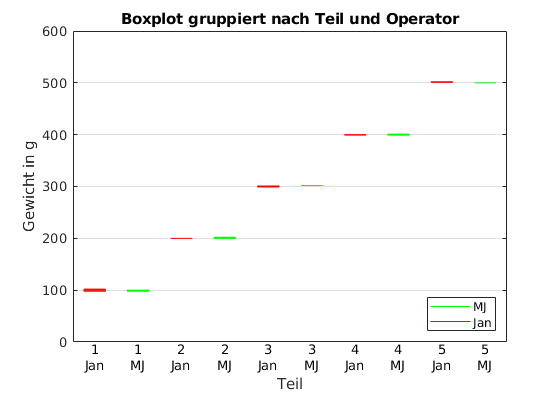

legend('Location','southeast')
title("Boxplot gruppiert nach Teil und Operator")
xlabel("Teil")
ylabel("Gewicht in g")
ylim([0 600])
grid on

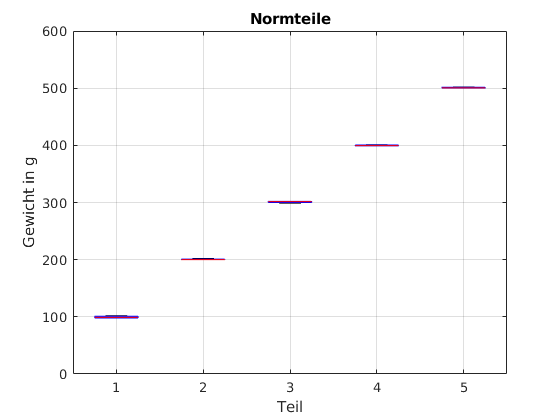


figure
boxplot(data_ms2_jan.Measurement,data_ms2_jan.Part)
title("Normteile")
xlabel("Teil")
ylabel("Gewicht in g")
ylim([0 600])
grid on

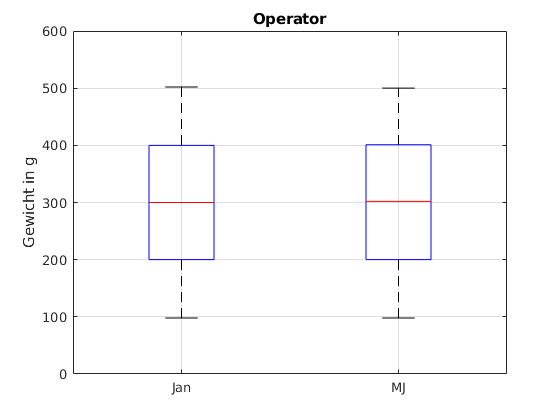


figure
boxplot(data_ms2_jan.Measurement,data_ms2_jan.Operator)
title("Operator")
ylabel("Gewicht in g")
ylim([0 600])
grid on

%Boxplot Benni
figure
boxplot(data_ms2_benni.Measurement,{data_ms2_benni.Part,...
    data_ms2_benni.Operator},"Colors","rg")
legend(findobj(gca,'Tag','Box'),'Marie','Benjamin')

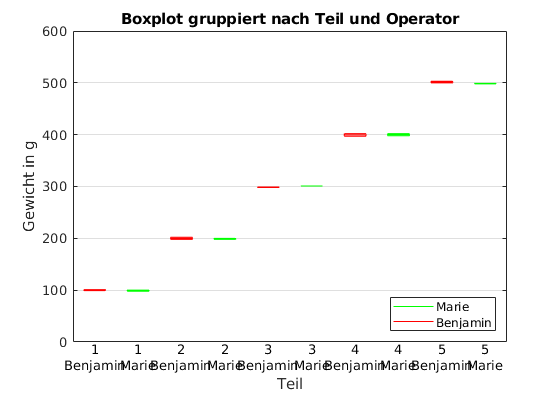

legend('Location','southeast')
title("Boxplot gruppiert nach Teil und Operator")
xlabel("Teil")
ylabel("Gewicht in g")
ylim([0 600])
grid on

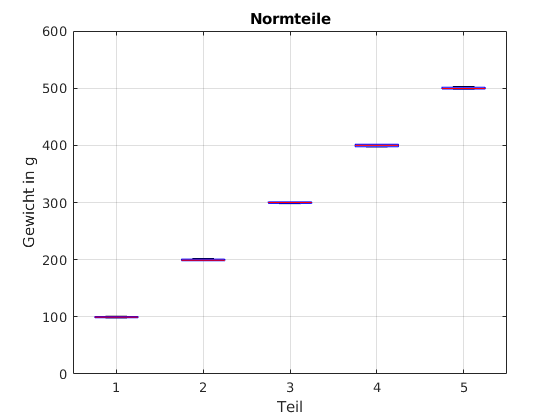


figure
boxplot(data_ms2_benni.Measurement,data_ms2_benni.Part)
title("Normteile")
xlabel("Teil")
ylabel("Gewicht in g")
ylim([0 600])
grid on

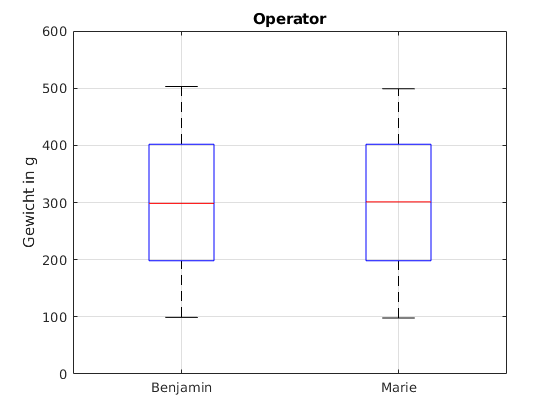


figure
boxplot(data_ms2_benni.Measurement,data_ms2_benni.Operator)
title("Operator")
ylabel("Gewicht in g")
ylim([0 600])
grid on

%Boxplot Anna
figure
boxplot(data_ms2_anna.Measurement,{data_ms2_anna.Part,...
    data_ms2_anna.Operator},"Colors","rg")
legend(findobj(gca,'Tag','Box'),'JL','Anna')

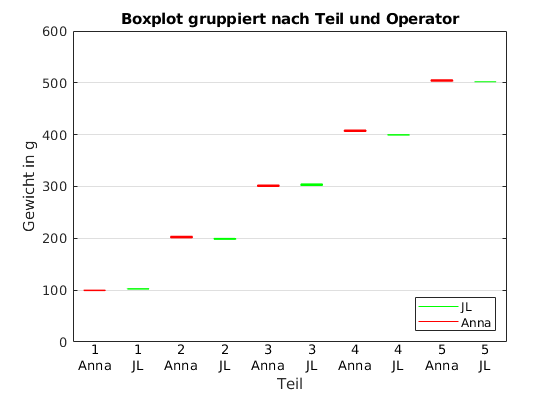

legend('Location','southeast')
title("Boxplot gruppiert nach Teil und Operator")
xlabel("Teil")
ylabel("Gewicht in g")
ylim([0 600])
grid on

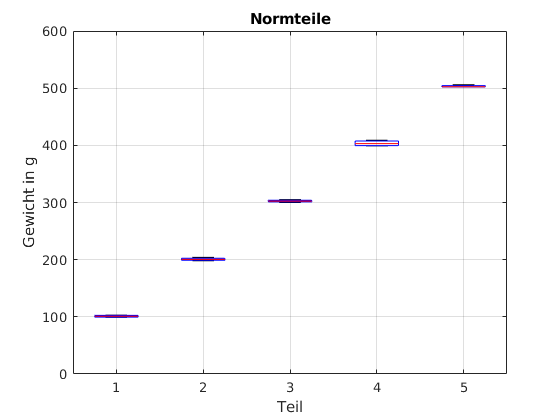


figure
boxplot(data_ms2_anna.Measurement,data_ms2_anna.Part)
title("Normteile")
xlabel("Teil")
ylabel("Gewicht in g")
ylim([0 600])
grid on

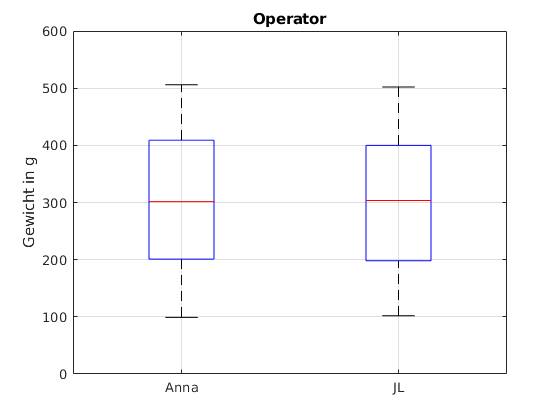


figure
boxplot(data_ms2_anna.Measurement,data_ms2_anna.Operator)
title("Operator")
ylabel("Gewicht in g")
ylim([0 600])
grid on


%Boxplot Michael
figure
boxplot(data_ms2_michael.Measurement,{data_ms2_michael.Part,...
    data_ms2_michael.Operator},"Colors","rg")
legend(findobj(gca,'Tag','Box'),'Michele','Michael')

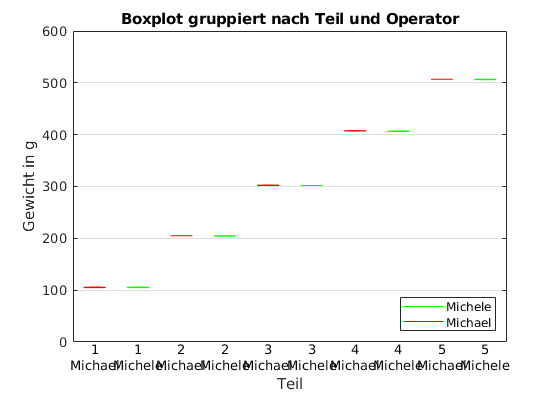

legend('Location','southeast')
title("Boxplot gruppiert nach Teil und Operator")
xlabel("Teil")
ylabel("Gewicht in g")
ylim([0 600])
grid on

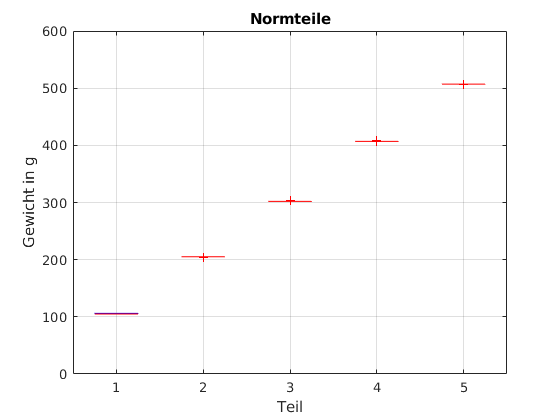


figure
boxplot(data_ms2_michael.Measurement,data_ms2_michael.Part)
title("Normteile")
xlabel("Teil")
ylabel("Gewicht in g")
ylim([0 600])
grid on

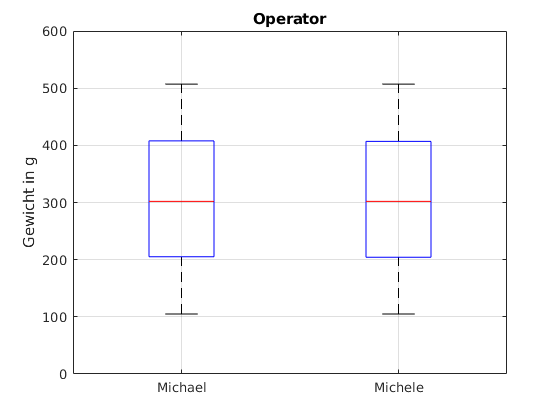


figure
boxplot(data_ms2_michael.Measurement,data_ms2_michael.Operator)
title("Operator")
ylabel("Gewicht in g")
ylim([0 600])
grid on

## Gage R&R

% GageErr
%Gage R&R durchführen
figure
gagerr(data_ms2_jan.Measurement,{data_ms2_jan.Part,...
    data_ms2_jan.Operator})

    {'Source'           }    {'Variance'  }    {'% Variance'}    {'sigma'   }    {'5.15*sigma'}    {'% 5.15*sigma'}
    {'Gage R&R'         }    {[    1.8071]}    {[    0.0072]}    {[  1.3443]}    {[    6.9231]}    {[      0.8487]}
    {'  Repeatability'  }    {[    1.8071]}    {[    0.0072]}    {[  1.3443]}    {[    6.9231]}    {[      0.8487]}
    {'  Reproducibility'}    {[         0]}    {[         0]}    {[       0]}    {[         0]}    {[           0]}
    {'   Operator'      }    {[         0]}    {[         0]}    {[       0]}    {[         0]}    {[           0]}
    {'Part'             }    {[2.5087e+04]}    {[   99.9928]}    {[158.3902]}    {[  815.7097]}    {[     99.9964]}
    {'Total'            }    {[2.5089e+04]}    {[       100]}    {[158.3959]}    {[  815.7391]}    {0×0 char      }

Number of distinct categories (NDC):167
% of Gage R&R of total variations (PRR):  0.85
Note: The last column of the above table does not have to sum to 100%


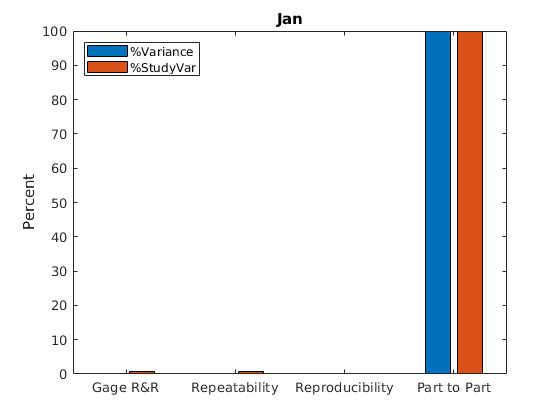

legend('Location',"northwest")
title("Jan")


figure
gagerr(data_ms2_benni.Measurement,{data_ms2_benni.Part,...
    data_ms2_benni.Operator})

    {'Source'           }    {'Variance'  }    {'% Variance'}    {'sigma'   }    {'5.15*sigma'}    {'% 5.15*sigma'}
    {'Gage R&R'         }    {[    4.0500]}    {[    0.0162]}    {[  2.0125]}    {[   10.3642]}    {[      1.2711]}
    {'  Repeatability'  }    {[    4.0500]}    {[    0.0162]}    {[  2.0125]}    {[   10.3642]}    {[      1.2711]}
    {'  Reproducibility'}    {[         0]}    {[         0]}    {[       0]}    {[         0]}    {[           0]}
    {'   Operator'      }    {[         0]}    {[         0]}    {[       0]}    {[         0]}    {[           0]}
    {'Part'             }    {[2.5062e+04]}    {[   99.9838]}    {[158.3083]}    {[  815.2880]}    {[     99.9919]}
    {'Total'            }    {[2.5066e+04]}    {[       100]}    {[158.3211]}    {[  815.3538]}    {0×0 char      }

Number of distinct categories (NDC):111
% of Gage R&R of total variations (PRR):  1.27
Note: The last column of the above table does not have to sum to 100%


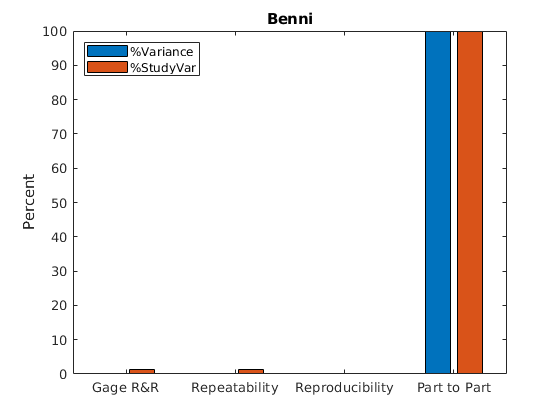

legend('Location',"northwest")
title("Benni")


figure
gagerr(data_ms2_anna.Measurement,{data_ms2_anna.Part,...
    data_ms2_anna.Operator})

    {'Source'           }    {'Variance'  }    {'% Variance'}    {'sigma'   }    {'5.15*sigma'}    {'% 5.15*sigma'}
    {'Gage R&R'         }    {[    8.3893]}    {[    0.0331]}    {[  2.8964]}    {[   14.9166]}    {[      1.8184]}
    {'  Repeatability'  }    {[    7.5214]}    {[    0.0296]}    {[  2.7425]}    {[   14.1240]}    {[      1.7218]}
    {'  Reproducibility'}    {[    0.8679]}    {[    0.0034]}    {[  0.9316]}    {[    4.7977]}    {[      0.5849]}
    {'   Operator'      }    {[    0.8679]}    {[    0.0034]}    {[  0.9316]}    {[    4.7977]}    {[      0.5849]}
    {'Part'             }    {[2.5362e+04]}    {[   99.9669]}    {[159.2552]}    {[  820.1644]}    {[     99.9835]}
    {'Total'            }    {[2.5371e+04]}    {[       100]}    {[159.2816]}    {[  820.3000]}    {0×0 char      }

Number of distinct categories (NDC):78
% of Gage R&R of total variations (PRR):  1.82
Note: The last column of the above table does not have to sum to 100%


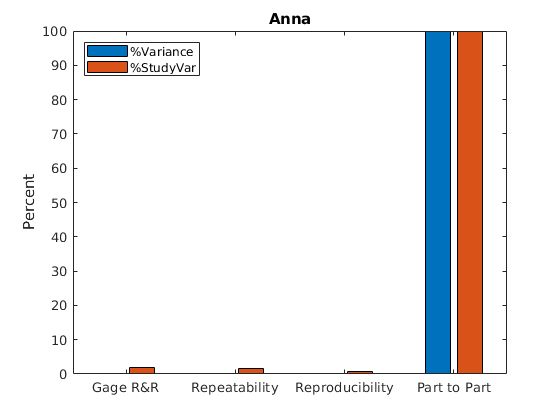

legend('Location',"northwest")
title("Anna")


figure
gagerr(data_ms2_michael.Measurement,{data_ms2_michael.Part,...
    data_ms2_michael.Operator})

    {'Source'           }    {'Variance'  }    {'% Variance'}    {'sigma'   }    {'5.15*sigma'}    {'% 5.15*sigma'}
    {'Gage R&R'         }    {[    0.2500]}    {[9.8961e-04]}    {[  0.5000]}    {[    2.5750]}    {[      0.3146]}
    {'  Repeatability'  }    {[    0.2083]}    {[8.2468e-04]}    {[  0.4564]}    {[    2.3506]}    {[      0.2872]}
    {'  Reproducibility'}    {[    0.0417]}    {[1.6494e-04]}    {[  0.2041]}    {[    1.0512]}    {[      0.1284]}
    {'   Operator'      }    {[    0.0417]}    {[1.6494e-04]}    {[  0.2041]}    {[    1.0512]}    {[      0.1284]}
    {'Part'             }    {[2.5262e+04]}    {[   99.9990]}    {[158.9406]}    {[  818.5441]}    {[     99.9995]}
    {'Total'            }    {[2.5262e+04]}    {[       100]}    {[158.9414]}    {[  818.5481]}    {0×0 char      }

Number of distinct categories (NDC):450
% of Gage R&R of total variations (PRR):  0.31
Note: The last column of the above table does not have to sum to 100%


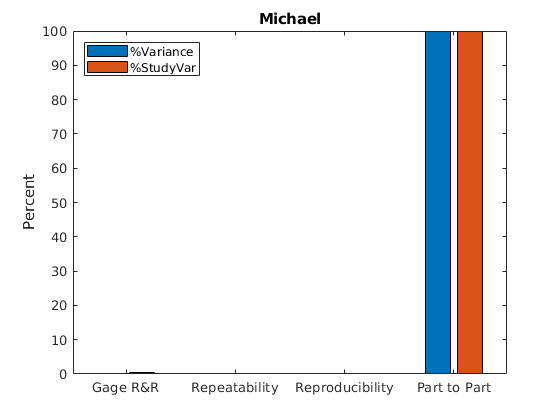

legend('Location',"northwest")
title("Michael")